## Analyzing Ice Melt

In this project, you’ll play the role of a scientist using satellite images to study climate change. You’ve been provided with two images of the same region in Antarctica taken two years apart. The first image was captured in January of 2018 and the second image was taken in January of 2020. Your goal is to calculate how much more water from melting is visible in the image taken two years after the first. 

Your task is to create a function that segments the water so you can compare the two image.

- Choose one of the images and use the Color Thresholder app to segment the image such that areas that are water are labeled true in the resulting binary image. 

- Generate the segmentation function and apply it to the other ice shelf image. 

- If you’re satisfied with the  performance of your function on both images, copy your function code into the online grader in the next section for assessment. Otherwise, go back to the Color Thresholder app and try a new approach on one of the images.

You’ll likely need to try multiple color spaces as it can be tricky to find a function that works with both images. Experiment with segmenting the first image and applying your function to the second and vice versa. Remember that you can change the background color and opacity in the app. This will help you identify where your segmentation is making mistakes.

You do not have to get a perfect segmentation. The online grader will provide feedback to help you adjust your approach. Once your function passes the assessment, calculate how much more water is visible in the 2nd ice shelf image. To help you, here is the resulting masked image using our segmentation function.

## Reading the Images

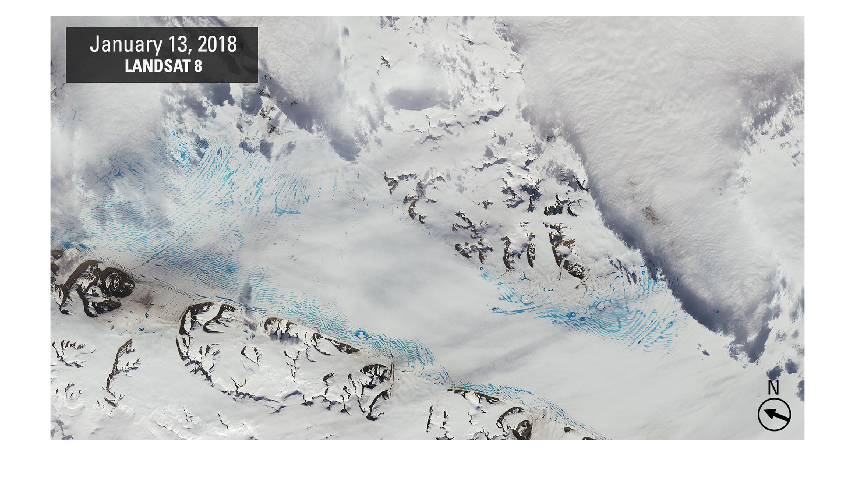

img1 = imread("1_SnowPoolsBefore_20180113_md-2048px.jpg");
img2 = imread("2_SnowPoolsAfter_20200119_md-2048px.jpg");

imshow(img1)

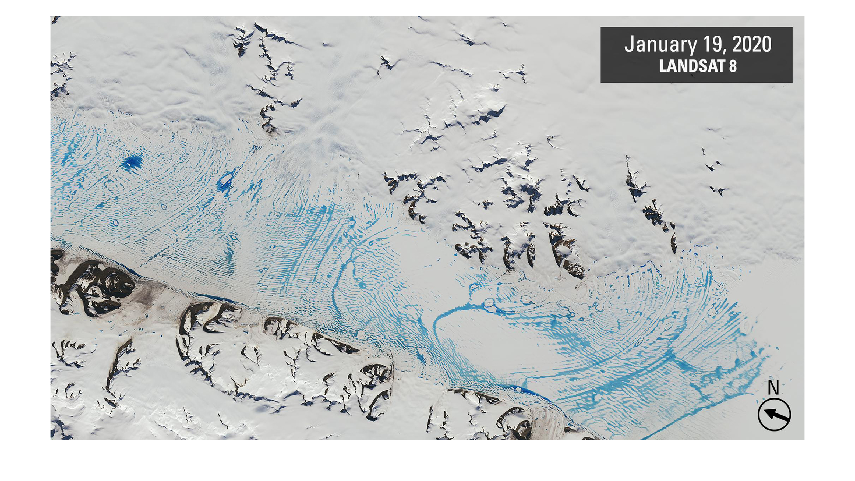

figure
imshow(img2)

## Masking the Images Using Segmentation Function

[BW1, maskedImg1] = analyzingIceMelt(img1);
[BW2, maskedImg2] = analyzingIceMelt(img2);

## Showing the Images Before/After Segmentation

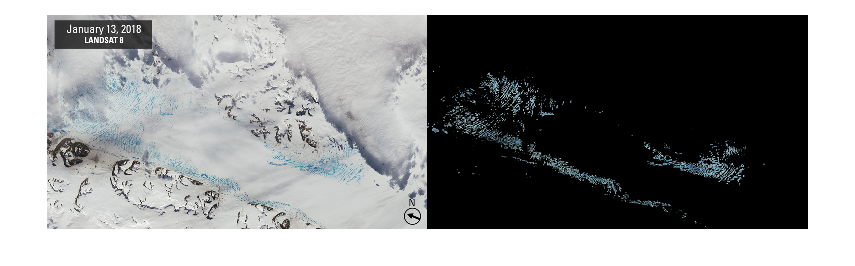

montage({img1, maskedImg1})

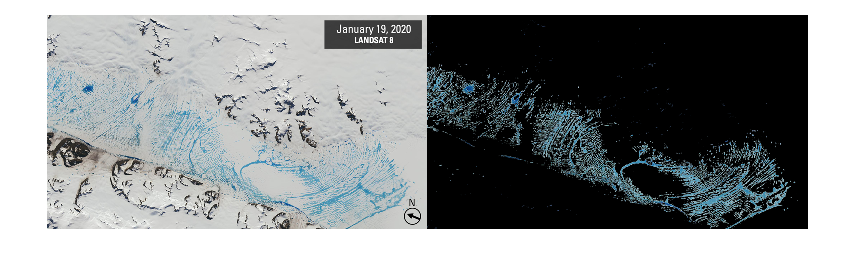

montage({img2, maskedImg2})

nnz(maskedImg1)

ans = 220690

nnz(maskedImg2)

ans = 688485

(nnz(maskedImg2) - nnz(maskedImg1)) / nnz(maskedImg1) * 100

ans = 211.9693

- Water has increased by 211.9693% between 2018 and 2020, so in 2020, it is a little over three times as much as in 2018.